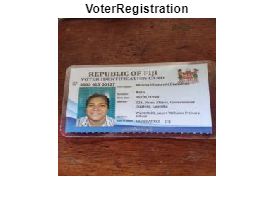

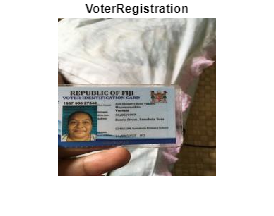

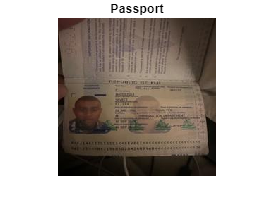

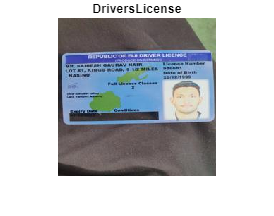

tic;
load('TrainedFijiIDCardClassifier.mat', 'netTransfer');

% Define the folder containing your test image dataset


% Load the test dataset
imdsTest = imageDatastore('IDDataTest', 'IncludeSubfolders', true, 'LabelSource', 'foldernames');

% Get the input size of the network
inputSize = netTransfer.Layers(1).InputSize;

% Resize the test images to match the input size of the network
augimdsTest = augmentedImageDatastore(inputSize(1:2), imdsTest);

% Classify the test images
[YPred, scores] = classify(netTransfer, augimdsTest);

% Display some example results
idx = randperm(numel(imdsTest.Files), 4);
for i = 1:4
    figure;
    imshow(imdsTest.Files{idx(i)});
    title(string(YPred(idx(i))));
end


% Get the actual labels (if available)
YTest = imdsTest.Labels;

% Calculate the accuracy (if labels are available)
if ~isempty(YTest)
    accuracy = mean(YPred == YTest);
    disp(['Test accuracy: ', num2str(accuracy)]);
end

Test accuracy: 0.99375



ConfusionMatrix = confusionmat(YTest,YPred)

ConfusionMatrix =     80     0     0     0
     0    80     0     0
     0     0    80     0
     0     2     0    78


toc;

Elapsed time is 4.081328 seconds.
